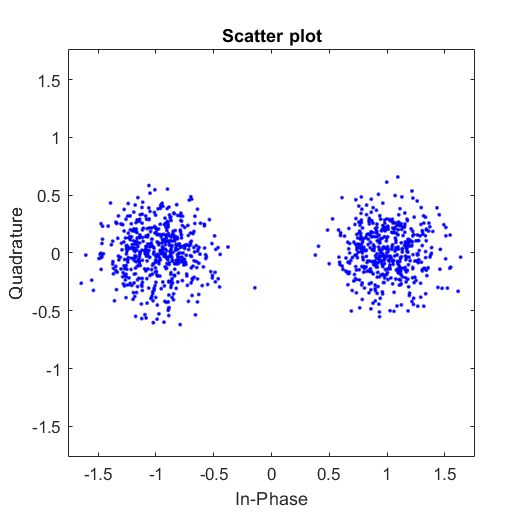

clear all
N_bits = 1000; % number of bits to transmit
EbNo_dB = 0:0.25:10; % SNR values in dB
Pe = zeros(size(EbNo_dB)); % initialize bit error rate vector

bpskModulator = comm.BPSKModulator;
bpskDemodulator = comm.BPSKDemodulator;
channel = comm.AWGNChannel('NoiseMethod', 'Signal to noise ratio (Eb/No)', 'EbNo', 0);


txData = randi([0 1], N_bits, 1); %Generate Data
txSig = bpskModulator(txData); %Modulate data
for i = 1:length(EbNo_dB)
    channel.EbNo = EbNo_dB(i);
    rxSig = channel(txSig);            % Pass through AWGN
    rxData = bpskDemodulator(rxSig);       % Demodulate
    err = comm.ErrorRate;
    x = err(txData, rxData);
    Pe(i) = x(1);
    %PE(i) = mean(abs(txData - rxData));
end

scatterplot(rxSig)

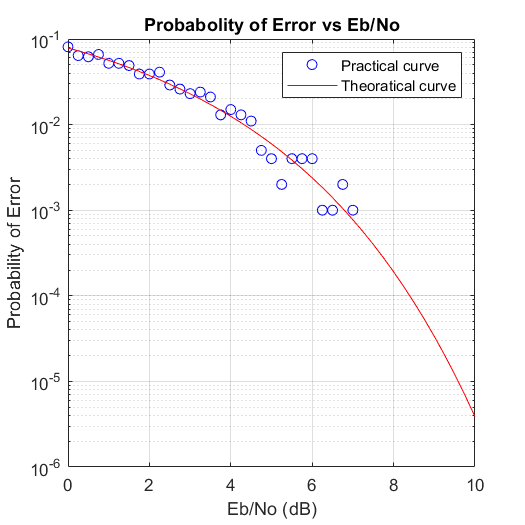

%display(Pe)
%display(PE)
%Pe = Pe./N_bits
EbNo = 10.^(EbNo_dB/10);
Pe_theoretical = (0.5)*erfc(sqrt(EbNo));
semilogy(EbNo_dB, Pe, 'bo', EbNo_dB, Pe_theoretical, 'r-')
%semilogy(EbNo_dB, PE, 'bo', EbNo_dB, Pe_theoretical, 'r-')
title ('Probabolity of Error vs Eb/No');
xlabel ('Eb/No (dB)');
ylabel ('Probability of Error');
legend('Practical curve','Theoratical curve');
grid on;